# Transformacja ortogonalna obrazu

% load data
img1 = imread('im1.png');
cameraman = imread('cameraman.tif');
img2 = imread('im2.png');

1)

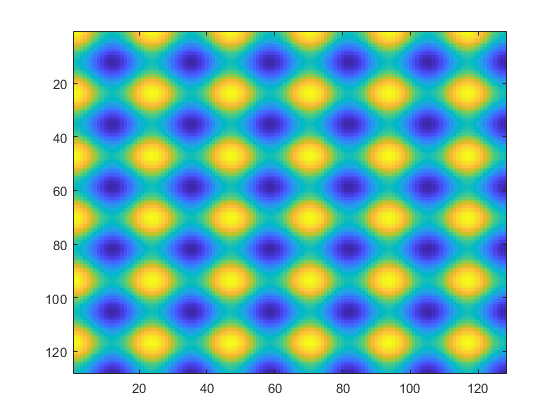

img1_dct2 = dct2(img1);

figure
imagesc(idct2(img1_dct2))

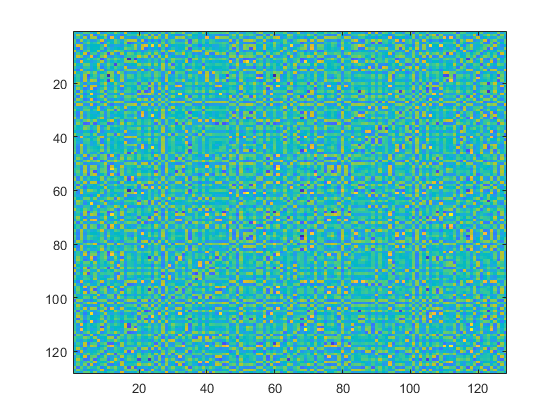


tmp_factor = img1_dct2(1,1);

img1_dct2_zeros = img1_dct2;
img1_dct2_zeros(1:64,1:64) = zeros(64);
img1_dct2_zeros(1,1) = tmp_factor;

figure
imagesc(idct2(img1_dct2_zeros))

2)

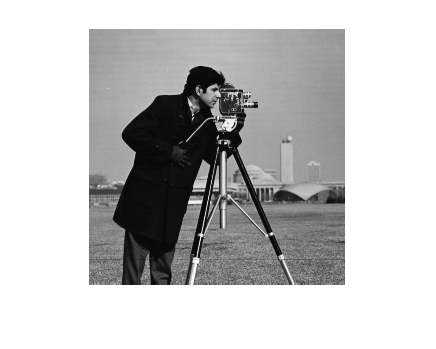

figure
imshow(cameraman)

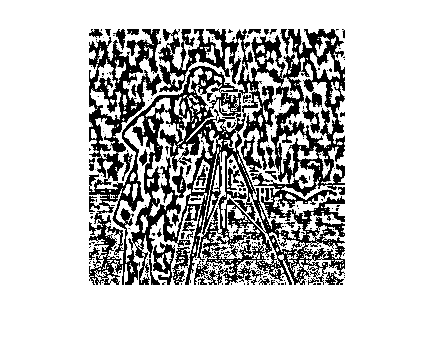


cam_dct2 = dct2(cameraman);

cam_dct_zeros = cam_dct2;
cam_dct_zeros(abs(cam_dct_zeros) > 100) = 0;

figure
imshow(idct2(cam_dct_zeros))

3)

I1=zeros(128,128); I1(2,10)=1; I1_idct=idct2(I1);
I2=zeros(128,128); I2(41,100)=1; I2_idct=idct2(I2);
I3=zeros(128,128); I3(111,3)=1; I3_idct=idct2(I3);
I4=zeros(128,128); I4(88,32)=1; I4_idct=idct2(I4);
I_idct = I1_idct + I2_idct + I3_idct + I4_idct

I_idct =     0.0307    0.0093    0.0277   -0.0005    0.0038    0.0146   -0.0066    0.0193    0.0026   -0.0067    0.0041   -0.0289   -0.0123   -0.0152   -0.0235    0.0066   -0.0139   -0.0024    0.0012   -0.0224    0.0039   -0.0092    0.0002    0.0246    0.0051    0.0288    0.0172    0.0033    0.0227   -0.0027    0.0155    0.0210    0.0041    0.0269   -0.0010   -0.0045   -0.0003   -0.0285   -0.0039   -0.0138   -0.0163    0.0039   -0.0254   -0.0120   -0.0186   -0.0337   -0.0040   -0.0192   -0.0011    0.0126
   -0.0080   -0.0027    0.0103    0.0146    0.0140    0.0051   -0.0122   -0.0221   -0.0292   -0.0263   -0.0155   -0.0103   -0.0060   -0.0124   -0.0246   -0.0316   -0.0370   -0.0292   -0.0152   -0.0031    0.0089    0.0076    0.0017   -0.0042   -0.0102   -0.0029    0.0077    0.0197    0.0304    0.0267    0.0192    0.0064   -0.0057   -0.0056   -0.0029    0.0063    0.0137    0.0096    0.0029   -0.0120   -0.0236   -0.0247   -0.0217   -0.0078    0.0035    0.0076    0.0081   -0.0021   -0.0082

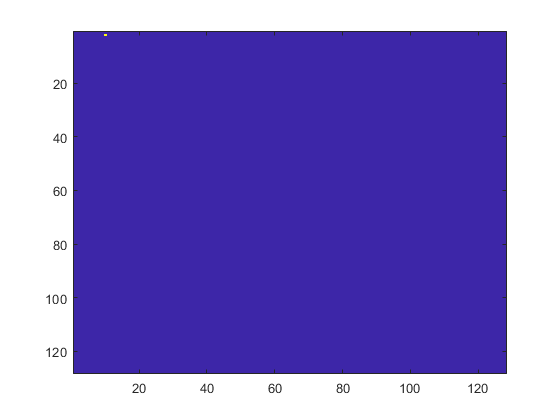


figure; imagesc(I1)

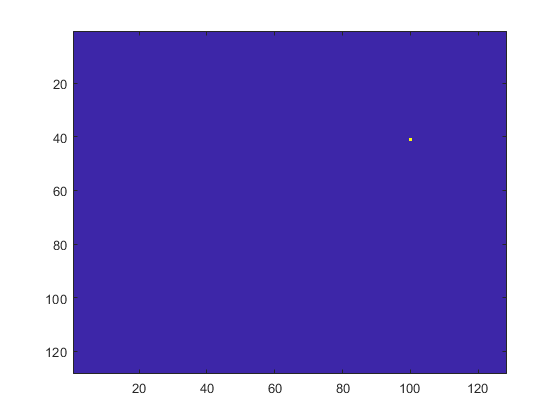

figure; imagesc(I2)

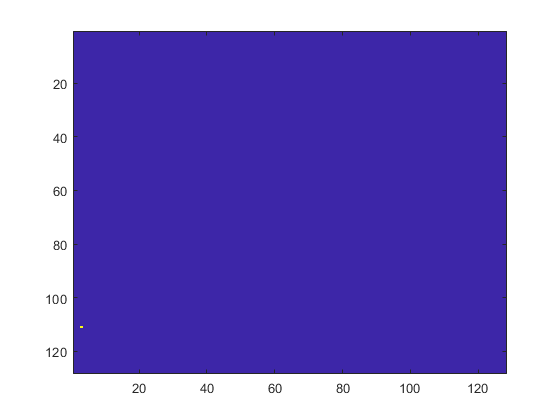

figure; imagesc(I3)

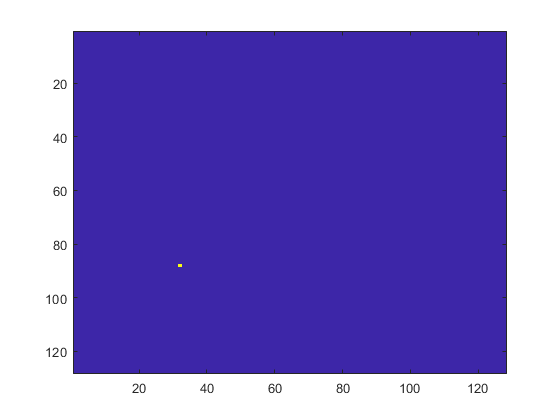

figure; imagesc(I4)

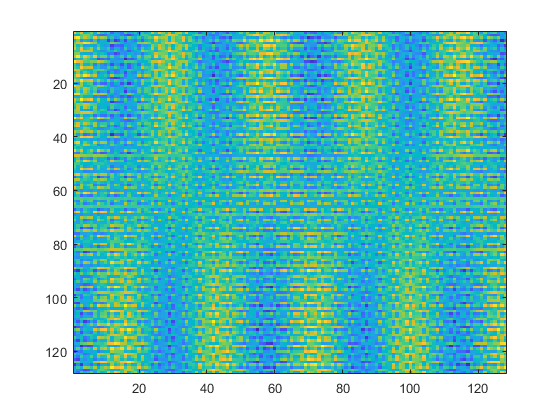


figure
imagesc(I_idct)

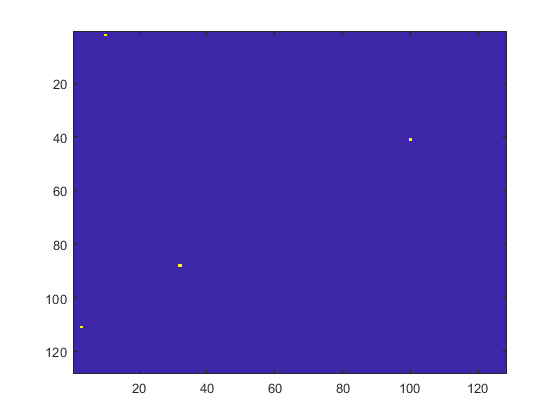


figure
imagesc(dct2(I_idct))

4) 

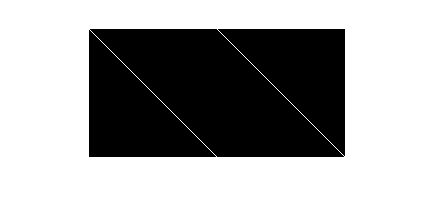

% imshow(log(abs(dct2(img2))), [])
figure; imshow([img2 dct2(img2)])

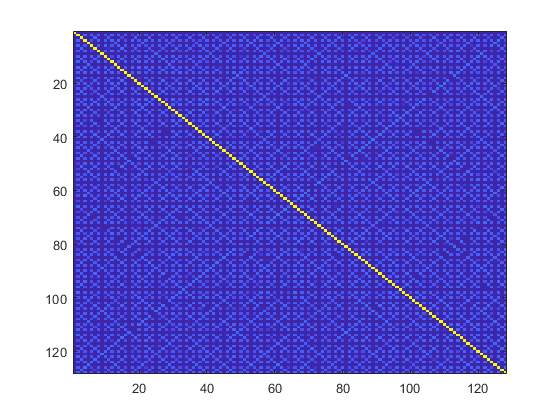

figure; imagesc(log(abs(dct2(img2))))